clc; clear;
K = 1.429; tau = 0.0031;
G = tf([K],[tau 1 0]);

Kv = 2000;
Kp = Kv/K

Kp = 1.3996e+03

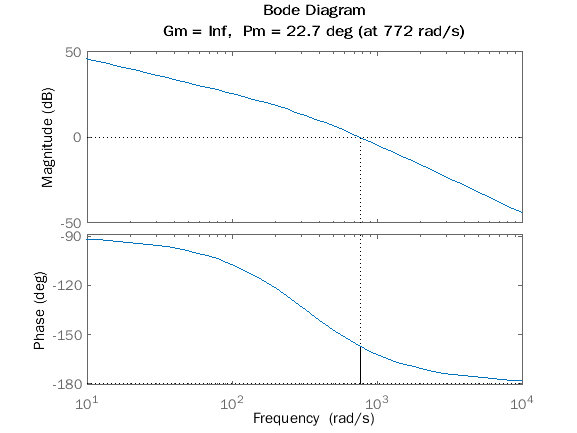

margin(Kp*G);

Cangle = (45 - 22.7) +5

Cangle = 27.3000

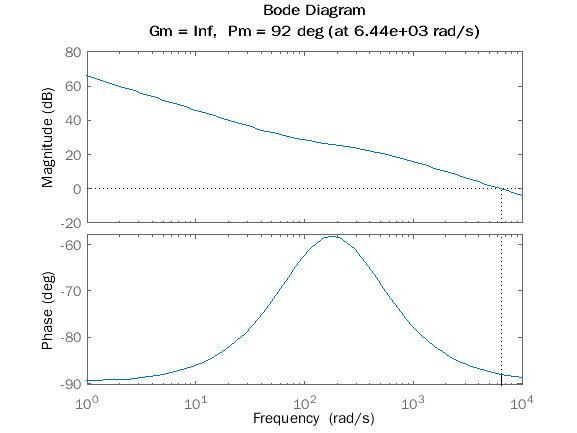

s = tf('s');
Td = 1/100;
margin(Kp*(1+Td*s)*G);


%clc; clear; warning off;
Kp = Kp;
KI = 0;
Kd = Kp*Td;

simout = sim('Lab_PositionControl.slx','StopTime','0.1');

Found algebraic loop containing: 
Lab_PositionControl/Gain4
Lab_PositionControl/Lead//Lag Compensator
Lab_PositionControl/Gain
Lab_PositionControl/Gain3
Lab_PositionControl/Gain2
Lab_PositionControl/Add
Lab_PositionControl/Manual Switch (discontinuity)
Lab_PositionControl/Saturation (discontin

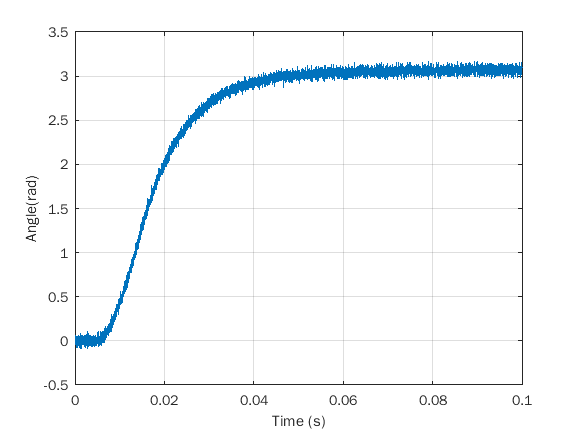


y = simout.theta;
u = simout.v;
t = simout.tout;
plot(t,y); grid on;
xlabel('Time (s)'); ylabel('Angle(rad)');


stepinfo(y,t)

ans = struct with fields:
         RiseTime: 0.0222
    TransientTime: 0.1000
     SettlingTime: 0.1000
      SettlingMin: 2.6730
      SettlingMax: 3.1697
        Overshoot: 1.9528
       Undershoot: 2.9146
             Peak: 3.1697
         PeakTime: 0.0893



ess = abs((pi) - mean(y(10000:end)))

ess = 0.3922

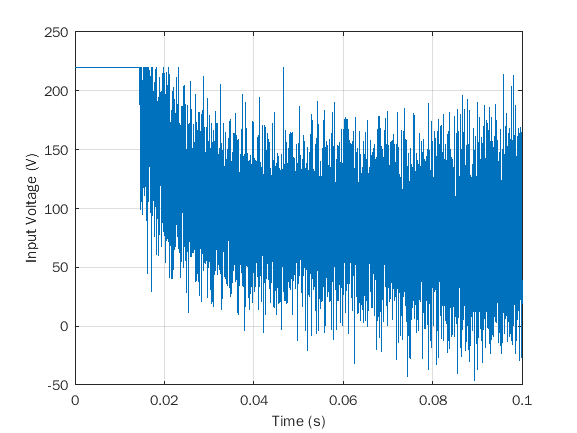


figure
plot(t,u); grid on;
xlabel('Time (s)'); ylabel('Input Voltage (V)');